Question 1.

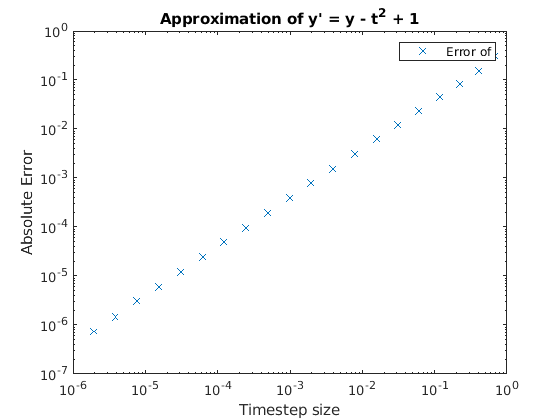

f = @(t,y) y - t.^2 + 1;
initVal = 0.5;
fwEulerVals = fwEuler(f, initVal);
yExact = @(t)(t+1).^2 - exp(t)/2;
exactVal = yExact(2);
err = abs(exactVal - fwEulerVals);
x = linspace(1,20,20);
x = 2./(2.^x + 1);
loglog(x, err, "x");
legend("Error of ");
ylabel("Absolute Error");
xlabel("Timestep size");
title("Approximation of y' = y - t^2 + 1");

While timestep size is low, error is lower.

Question 2.

t = [0 2];
[t, y] = ode45(f,t,0.5);
numel(t)

ans = 45

y(numel(y))

ans = 5.3055

ode45 needs 45 points for this particular ODE to reach a value of 5.3055 for t = 2.

function Y = fwEuler(f, iv)
    Y = zeros(1, 20);
    for k = 1:20
        T = linspace(0,2,2^k+1);
        deltaT = abs(T(1) - T(2));
        y = iv;
        for i = 1:numel(T)
            y = y + (deltaT).*(f(T(i), y));
        end
        Y(k) = y;
    end 
end